# CubeSat Mission Analysis with Mapping Toolbox

This example shows how to analyze mission geometry calculated during simulation with Mapping Toolbox™ `worldmap` and `geoshow` functions.  

The analysis demonstrates how to:

- Display the satellite orbit over the analyzed time.

- Display global and regional ground traces over the analyzed time.

- Determine satellite camera field of view (FOV) at a specific time of interest (TOI).

## Run the Simulation

Run the simulation if the simulation output object `out` does not exist. 

arch.model = "asbCubeSatArchModel";
if ~exist('out','var')
    open_system(arch.model);
    out = sim(arch.model);
end

Updating initCond structure with initial values from stereotypes defined in:
  asbCubeSatArchModel/CubeSat Mission Enterprise (CubeSatProfile.CubeSatEnterprise)
  asbCubeSatArchModel/CubeSat Mission Enterprise/Space Segment/CubeSat Initial Orbit (CubeSatProfile.Orbit)
  asbCubeSatArchModel/CubeSat Mission Enterprise/Space Segment/CubeSat Initial Attitude (CubeSatProfile.Attitude)
Update complete.


Get simulation start date from the `CubeSatProfile.CubeSatEnterprise` stereotype definition in component `asbCubeSatArchModel/CubeSat Mission Enterprise`.

arch.cubeSatModel = systemcomposer.loadModel(arch.model);
mission.startDateJD = eval(getProperty(arch.cubeSatModel.lookup("Path", ...
    "asbCubeSatArchModel/CubeSat Mission Enterprise"), ...
    "CubeSatProfile.CubeSatEnterprise.MissionStartDate"));
mission.startDate = datetime(mission.startDateJD, ConvertFrom="juliandate");

## Extract simulation data from model output

Extract the logged position data from the simulation output structure.

cubesat.lla = out.yout{1}.Values.LatLonAlt;

Set the start time of the **timetable** object to the mission start date.

cubesat.lla.Properties.StartTime = mission.startDate;
cubesat.lla = splitvars(cubesat.lla, "Data", NewVariableNames=["lat", "lon", "alt"]);
disp(head(cubesat.lla))

            Time             lat        lon         alt    
    ____________________    ______    _______    __________

    01-Jul-2019 11:00:00    5.3932     -27.24    1.6741e+06
    01-Jul-2019 11:00:01    5.4421    -27.256    1.6741e+06
    01-Jul-2019 11:00:02    5.4911    -27.272    1.6741e+06
    01-Jul-2019 11:00:03      5.54    -27.288    1.6741e+06
    01-Jul-2019 11:00:03      5.58    -27.301    1.6741e+06
    01-Jul-2019 11:00:04    5.5889    -27.304    1.6741e+06
    01-Jul-2019 11:00:05    5.6378    -27.319    1.6741e+06
    01-Jul-2019 11:00:06    5.6868    -27.335    1.6741e+06



## Results

### **Display Satellite Trajectories Over the 3D Globe**

Display the satellite trajectories over Earth (WGS84 ellipsoid).

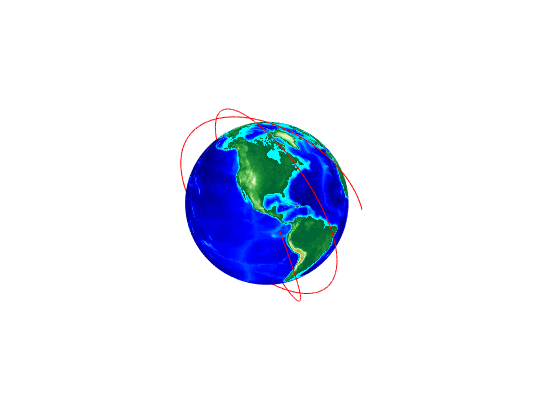

mission.globe = load("topo.mat", "topo", "topolegend");
mission.globe.reference = wgs84Ellipsoid;
figure;
axesm("globe", Geoid=mission.globe.reference);
axis off; 
geoshow(mission.globe.topo, mission.globe.topolegend, DisplayType="surface");
demcmap(mission.globe.topo);
view(-5, 23);
plot3m(cubesat.lla.lat, cubesat.lla.lon, cubesat.lla.alt, 'r');

### Display Global and Regional 2D Ground Traces

View the global ground trace as a 2D projection.

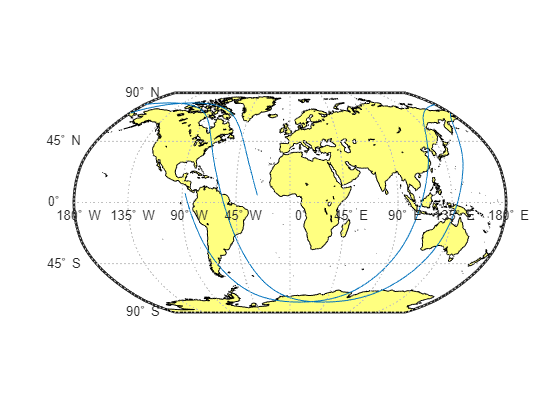

figure;
worldmap("World");
geoshow("landareas.shp");
plotm(cubesat.lla.lat, cubesat.lla.lon);

View regional ground trace over the continental US (CONUS).

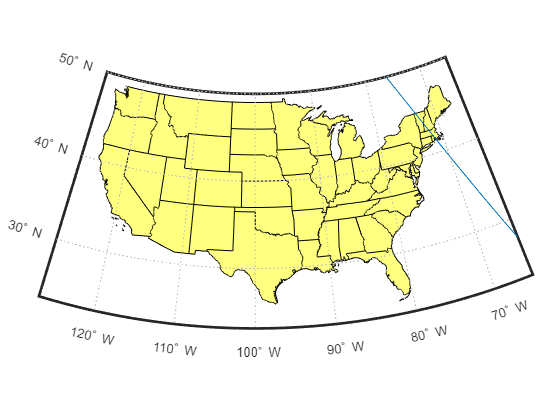

figure;
usamap("conus");
mission.globe.usStates = shaperead("usastatehi", UseGeoCoords=true); 
geoshow(mission.globe.usStates);
plotm(cubesat.lla.lat, cubesat.lla.lon);

View a custom region defined by latitude and longitude bounds with imaging target indicated by a green triangle.

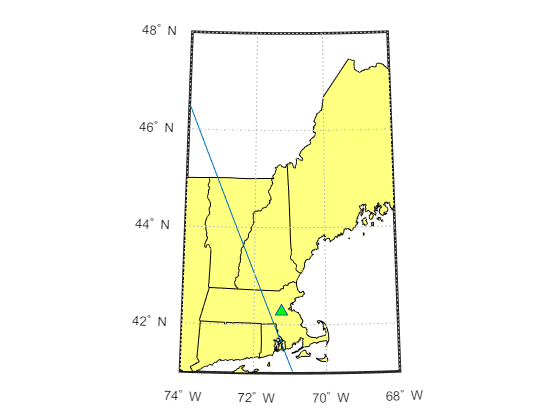

grndStation.lat = 42.2775; % deg (at MathWorks HQ)
grndStation.lon = -71.2468; % deg (at MathWorks HQ)
figure;
worldmap([41, 48], [-74, -68]); % [latMin, latMax], [lonMin, lonMax]
geoshow(mission.globe.usStates);
plotm(cubesat.lla.lat, cubesat.lla.lon);
plotm(grndStation.lat, grndStation.lon, 'b^', MarkerSize=8, MarkerFaceColor="g")

### Display Instrument Field of View (FOV) at Time of Interest (TOI)

- Sub-satellite point is indicated by a red cross.

- Camera FOV is indicated by a solid blue circle.

Access TOI position data.

toi.time = datetime(2019, 7, 1, 13, 12, 32);
toi.lla = retime(cubesat.lla, toi.time);

Plot field of view.

figure;
worldmap([41, 48], [-74, -68]); % [latMin, latMax], [lonMin, lonMax]
geoshow(mission.globe.usStates);
title(string(toi.time));

Plot ground station, satellite ground trace, and sub-satellite point at TOI.

plotm(grndStation.lat, grndStation.lon, "b^", MarkerSize=8, MarkerFaceColor="g");  % ground station
plotm(cubesat.lla.lat, cubesat.lla.lon);                                                   % satellite ground trace
plotm(toi.lla.lat,toi.lla.lon, "r+", MarkerSize=8);                                % sub-satellite point

Calculate geometry of camera field of view.

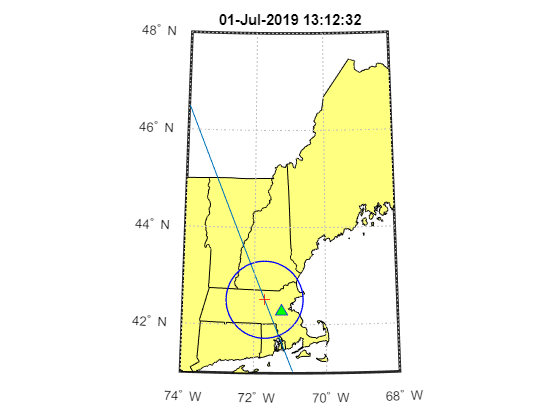

mission.globe.r = earthRadius('m');
camera.fov.halfAngle = 3; % deg
toi.fov.rho = asind(mission.globe.r / (mission.globe.r + toi.lla.alt));  % deg, angular radius of Earth as seen from the satellite
toi.fov.epsilon = acosd(sind(camera.fov.halfAngle) / sind(toi.fov.rho)); % deg, satellite elevation angle
toi.fov.lambda = 90 - camera.fov.halfAngle - toi.fov.epsilon;            % deg, angular radius of camera FOV measured from Earth center
[toi.fov.lats, toi.fov.lons] = scircle1(toi.lla.lat, toi.lla.lon, toi.fov.lambda);
plotm(toi.fov.lats, toi.fov.lons, "b", LineWidth=1)

### References

[1] Wertz, James R, David F. Everett, and Jeffery J. Puschell. *Space Mission Engineering: The New Smad*. Hawthorne, CA: Microcosm Press, 2011. Print.

*Copyright 2021 The MathWorks, Inc.*